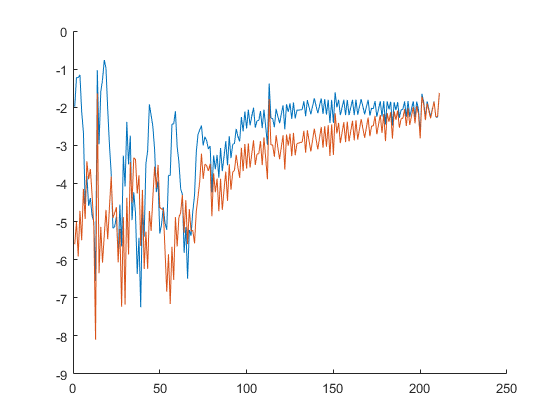

N = length(Accel);
samp = 300;
t = Accel(samp:end, 1);
ax = low_pass_filter(samp, Accel(:, 2));
ay = low_pass_filter(samp, Accel(:, 3));
az = low_pass_filter(samp, Accel(:, 4));

t_step = diff(t);
vx = ax(1:end-1) .* t_step;
vy = ay(1:end-1) .* t_step;
vz = az(1:end-1) .* t_step;

figure
hold on
plot(vx)
plot(vy)

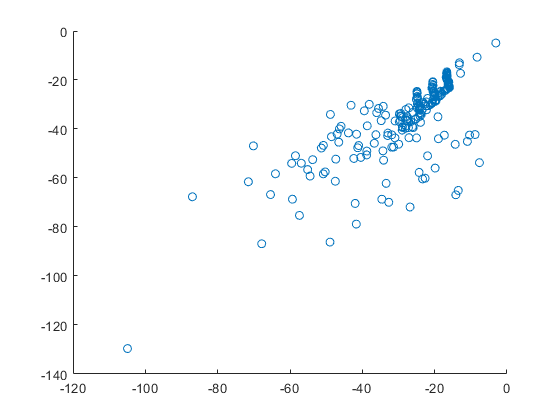


x = vx .* t_step;
y = vy .* t_step;
z = vz .* t_step;

figure
hold on
scatter(x, y)


% plot(t,Accel(:,2))
% hold on
% plot(t,Accel(:,3))
% hold off
% filtAccel = lowpass(Accel,1, 100);
% plot(t,filtAccel(:,2))
% hold on
% plot(t,filtAccel(:,3))
% hold off
% velx = cumtrapz(t,filtAccel(:,2));
% vely = cumtrapz(t,filtAccel(:,3));
% plot(velx)
% hold on
% plot(vely)
% hold off
% posx = cumtrapz(t, velx);
% posy = cumtrapz(t, vely);
% plot(posx)
% hold on
% plot(posy)
% hold off
% scatter(posx,posy)
% axis equal



function low_pass = low_pass_filter(samp, data)
    low_pass = data;
    for k = [samp:length(data)]
        res = (1/sum(1:samp))*(1:samp)*data(k-samp+1:k);
%         res = (1/12)*(data(k) + 5*data(k-1) + 4*data(k-2) + 3*data(k-3) + 2*data(k-4) + data(k-5));
        low_pass(k) = res;
    end
    low_pass = low_pass(samp:length(low_pass));
end